# 通信原理实验5

姓名：朱天昊

学号：18308267

邮箱：1312622783@qq.com

## 实验目标

`（1）近似非带限信道下的数字基带传输；`

`（2）带限信道下的数字基带传输。`

## 实验条件

MATLAB 2016 and above, Simulink, and Communications System Toolbox .

## Prelab

## Problem 1  正交信号、双极性信号、单极性信号在AWGN信道下的传输性能

正交信号$\left\lbrace \begin{array}{cc}
s_0 \left(t\right)=1 & 0\le t\le T_b \\
s_1 \left(t\right)=\left\lbrace \begin{array}{cc}
1 & 0\le t\le \frac{T_b }{2}\\
-1 & \frac{T_b }{2}\le t\le T_b 
\end{array}\right. & 
\end{array}\right.$

双极性信号$\left\lbrace \begin{array}{cc}
s_0 \left(t\right)=1 & 0\le t\le T_b \\
s_1 \left(t\right)=-1 & 0\le t\le T_b 
\end{array}\right.$

单极性信号 $\left\lbrace \begin{array}{cc}
s_0 \left(t\right)=1 & 0\le t\le T_b \\
s_1 \left(t\right)=0 & 0\le t\le T_b 
\end{array}\right.$

发送信号分别如上所示，每个信号周期取样10次，接收端采用相关器接收，试画出误比特率随$\frac{E_b }{N_0 }$的变化情况，$\frac{E_b }{N_0 }$的范围是0~12dB，并与理论值进行比较。

**Answer:**

% insert your code here
% 一、正交信号
clc; close all; clear all;
Ns = 10;    % Ns为对一个码元的采样点数（由于这里是二进制基带信号，一个码元就是一个比特）

% 定义正交信号s0(t)和s1(t)。
s0 = ones(1, Ns);
s1 = [ones(1,Ns/2), -ones(1,Ns/2)];
nsym = 100000;   
% 注：本次程序默认s0(t)表示比特"0"，s1(t)表示比特"1"。

EbN0 = 0:12;    % 比特信噪比的变化范围
msg = randi([0,1], 1, nsym);  % 假设有100000比特的信号需传输，它01出现概率随机
% msg就是二进制比特流
s00 = zeros(nsym, 1);   
s11 = zeros(nsym, 1);
indx0 = find(msg==0);

debug


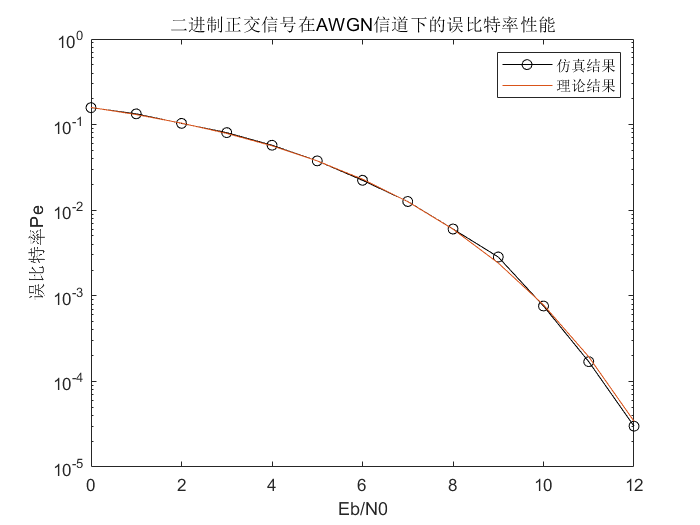

s00(indx0) = 1;     
s00 = s00*s0;       % 比特"0"映射为波形s0(t)
indx1 = find(msg==1);
s11(indx1) = 1;
s11 = s11*s1;     % 比特"1"映射为波形s1(t)
s = s00 + s11;      
s = s';

for i=1:length(EbN0)
    decmsg = zeros(1, nsym);
    r = awgn(s, EbN0(i)-7);    % 由于awgn读取的输入参数是SNR,根据公式"Eb/N0=SNR+10lg(Tsym/Tsamp)"对Eb/N0进行变换
    r00 = s0*r;
    r11 = s1*r;      % 行向量与列向量相乘，得到的便是相关积分（求和）的结果
    
    indx1 = find(r11>= r00);  % 正交信号经过相关器后通过判断r0与r1的大小关系来进行判决。
    
    decmsg(indx1) = 1;    % r11>=r00时，判为比特"1"
    [err, ber(i)] = biterr(msg, decmsg);  % biterr函数的输入变量是两串二进制比特流，可返回这两串比特流的误比特率
    % ber就是误比特率数组
end
semilogy(EbN0, ber, '-ko', EbN0, qfunc(sqrt(10.^(EbN0/10))));
title('二进制正交信号在AWGN信道下的误比特率性能')
xlabel('Eb/N0'); ylabel('误比特率Pe');
legend('仿真结果','理论结果')



% 二、双极性信号

Ns = 10;

% 定义双极性信号s0(t)和s1(t)。
s0 = ones(1, Ns);
s1 = -ones(1, Ns);

nsym = 100000;

EbN0 = 0:12;
msg = randi([0,1], 1, nsym);
s00 = zeros(nsym, 1);
s11 = zeros(nsym, 1);
indx0 = find(msg==0);

debug


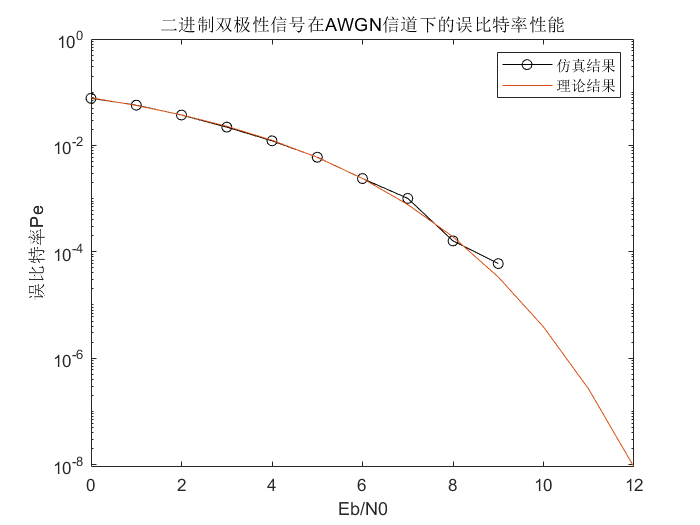

s00(indx0) = 1;   
s00 = s00*s0;       
indx1 = find(msg==1);
s11(indx1) = 1;
s11 = s11*s1;
s = s00 + s11;      
s = s';

for i=1:length(EbN0)
    decmsg = zeros(1, nsym);
    r = awgn(s, EbN0(i)-7);    
    r00 = s0*r;
    indx1 = find(r00<0);      % 判决条件与正交信号有所不同，是根据r与0的关系判决的
    decmsg(indx1) = 1;
    [err, ber(i)] = biterr(msg, decmsg); 
end
semilogy(EbN0, ber, '-ko', EbN0, qfunc(sqrt(2*10.^(EbN0/10))));
title('二进制双极性信号在AWGN信道下的误比特率性能')
xlabel('Eb/N0'); ylabel('误比特率Pe');
legend('仿真结果','理论结果')

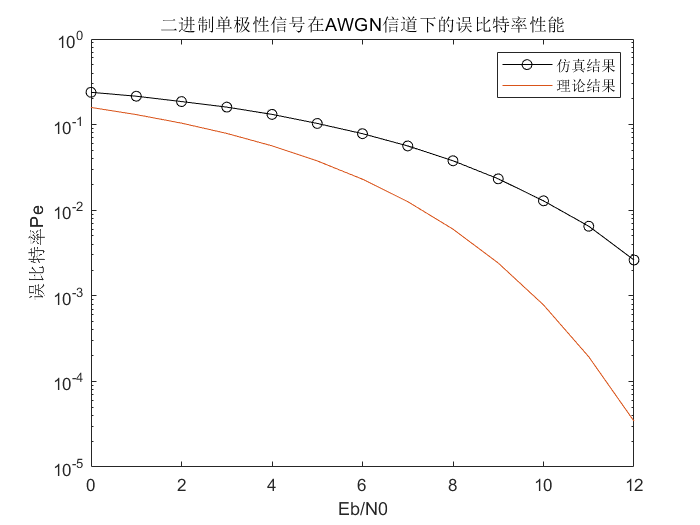


% 三、单极性信号

Ns = 10;

s0 = ones(1, Ns);
s1 = zeros(1, Ns);

nsym = 100000;

EbN0 = 0:12;
msg = randi([0,1], 1, nsym);
s00 = zeros(nsym, 1);
s11 = zeros(nsym, 1);
indx0 = find(msg==0);

s00(indx0) = 1;   
s00 = s00*s0;      
indx1 = find(msg==1);
s11(indx1) = 1;
s11 = s11*s1;
s = s00 + s11;      
s = s';

for i=1:length(EbN0)
    decmsg = ones(1, nsym);
    r = awgn(s, EbN0(i)-7); 
    r00 = s0*r;
    indx1 = find(r00>5);    % 判决门限是r与5的关系
    decmsg(indx1) = 0;
    [err, ber(i)] = biterr(msg, decmsg); 
end
semilogy(EbN0, ber, '-ko', EbN0, qfunc(sqrt(10.^(EbN0/10))));
title('二进制单极性信号在AWGN信道下的误比特率性能')
xlabel('Eb/N0'); ylabel('误比特率Pe');
legend('仿真结果','理论结果')

**仿真结果分析：**

1）正交信号误比特率的仿真结果与理论结果拟合得最好。正交信号同时使用s0(t)和s1(t)的接收信号r进行相关处理，最后对相关处理后的结果r0和r1进行比较判决。在判决时刻Ts，若r1(Ts)>=r0(Ts)，就判为比特“1”，反之则判为比特“0”。

2）双极性信号由于s0(t)和s1(t)的幅值相反，在接收时只需使用s0(t)和s1(t)其中一个对接收信号r进行互相关处理（本例代码使用s0(t)对r求互相关）。在判决时刻Ts，若r0(Ts)<=0，就判为比特“1”，反之则判为比特“0”。

3）单极性信号在做相关接收时，其输出信号r00幅度会变为原来的十倍，所以判决门限也要随之改变，变为5。

## Problem 2  基带4PAM信号在AWGN信道下的传输

仿真4-PAM信号通过AWGN信道后的误比特率性能。比特映射采用格雷编码，接收端采用相关器，试画出误比特率和误符号率随$\frac{E_s }{N_0 }$的变化情况，$\frac{E_s }{N_0 }$的范围是0~15dB，并与理论值进行比较。

**Answer:**

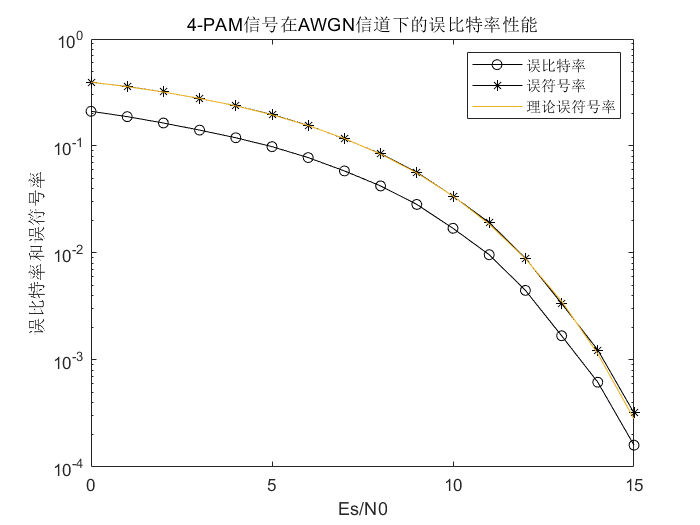

% insert your code here
clc; close all; clear all;
Ns = 10;

M = 4;

nsym = 100000;
grcode = [0,1,3,2];
% 格雷码译码规则：0:00  1:01  2:11  3:10

EsN0 = 0:15;      
msg = randi([0,3], 1, nsym); % msg是一串符号流，每个符号随机取值0,1,2,3
msg1 = grcode(msg+1);
msg2 = pammod(msg1, M);    % pammod可对PAM信号进行调制

s = rectpulse(msg2, Ns);    % 矩形脉冲成形，每个码元有10个采样点

for i=1:length(EsN0)
    decmsg = zeros(1, nsym);
    r = awgn(real(s), EsN0(i)-7, 'measured');    
    r1 = intdump(r, Ns);
    msg_demod = pamdemod(r1, M);    % pamdemod可对已调PAM信号进行解调
    decmsg = grcode(msg_demod+1);
    [err, ber(i)] = biterr(msg, decmsg, log2(M));  
    [err, ser(i)] = symerr(msg, decmsg);  % symerr返回两串码流的误码率
end
semilogy(EsN0, ber, '-ko',EsN0, ser, '-k*', EsN0, 1.5*qfunc(sqrt(0.4*10.^(EsN0/10))));
title('4-PAM信号在AWGN信道下的误比特率性能')
xlabel('Es/N0'); ylabel('误比特率和误符号率');
legend('误比特率','误符号率','理论误符号率')

**仿真结果分析：**

1）本题使用的基带信号是4PAM信号，每个码元有四种不同的取值。所以在分析误码率图像时，需要用符号信噪比Es/N0作为横坐标进行分析。同时若要在误码率的图像显示误比特率，biterr还需一个输入变量log2(M)。

2）4PAM使用格雷码编码，将信息比特对映射为4种波形，如下：

00: s0(t)    01: s1(t)  11: s2(t)  10: s3(t)

3）基带4PAM信号采用相关器作为最佳接收。它将接收信号r(t)与信号脉冲信号g(t)做互相关，将输出信号采样。检测器将根据输出与4种可能传输点平进行比较，选择欧式距离最接近r的幅度电平作为判决结果。

## Lab

## **Problem 1 升余弦滤波器设计**

设计一个滚降系数为0.2，时延为4个符号间隔的FIR升余弦滤波器，其中符号采样频率$F_d =1$,滤波器采样频率为$F_s =10$。画出该滤波器的冲激响应，并生成30个二进制数据序列，对该序列进行滤波，划出滤波前后的波形。

**Answer:**

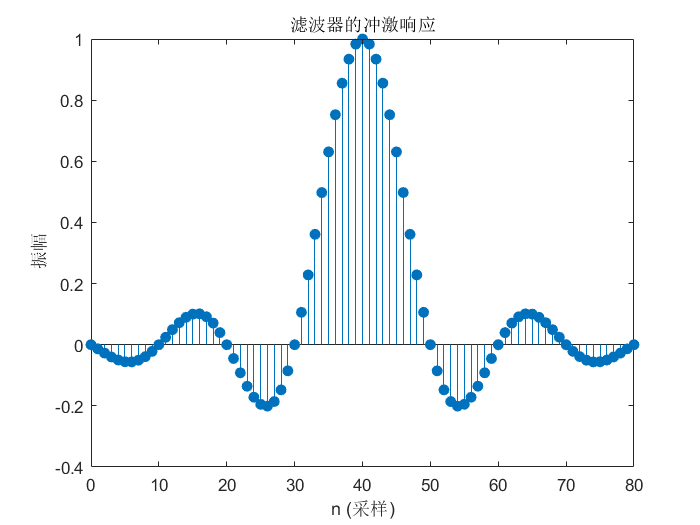

% insert your code here
clc; close all; clear all;

Fd = 1;
Fs = 10;
alpha = 0.2;
delay = 4;
[num, den] = rcosine(Fd, Fs, 'default', alpha, delay);

impz(num, 1);  % 因为是FIR滤波器，所以分母系数a为1
title('滤波器的冲激响应');

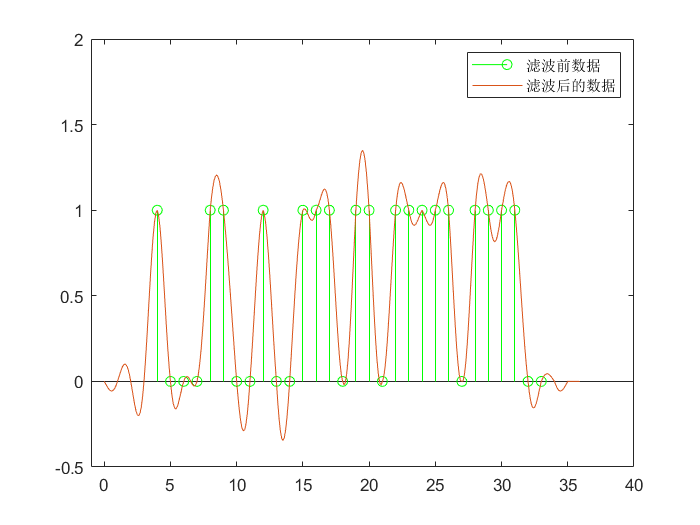

figure;

msg = randi([0,1], 1, 30);
[y, ty] = rcosflt(msg, Fd, Fs, 'filter', num, den);
t = delay:length(msg) + delay -1;
stem(t, msg, 'g');
hold on;
plot(ty, y);
legend('滤波前数据', '滤波后的数据')
axis([-1 40 -0.5 2])

**仿真结果分析：**

1）matlab系统自带的rcosine函数可通过符号采样频率Fd、滤波器采样频率Fs、滚降系数alpha和时延delay直接得到根升余弦滤波器，并返回该滤波器系统函数分子分母的系数【b,a】。而rcosflt函数可直接将比特流作为输入变量，得到的输出变量既是基带信号的滤波结果。

2）由于滤波器使得基带信号的频率变窄，所以输出信号的时域会变宽，且输出信号为连续谱。

## **Problem 2  带限数字基带传输**

一个4-PAM调制信号，在发送端和接收端分别采用滚降系数为0.25、时延为5的根升余弦滤波器进行脉冲成形与脉冲检测，其中符号采样频率$F_d =1$,滤波器采样频率为$F_s =10$。比特映射采用格雷编码，仿真该信号在AWGN信道下的传输性能。试画出误比特率和误符号率随$\frac{E_s }{N_0 }$的变化情况，$\frac{E_s }{N_0 }$的范围是0~15dB，并与理论值进行比较。

**Answer:**

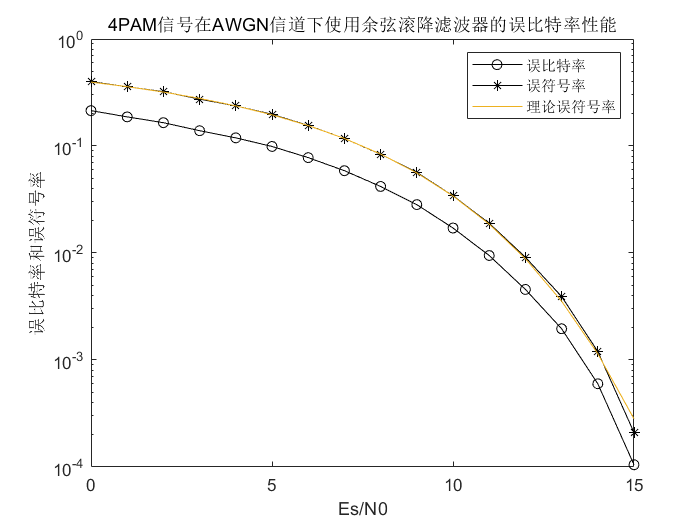

% insert your code here
clc; close all; clear all;
nsym = 100000;

Fd = 1;
Fs = 10;
rolloff = 0.25;
delay = 5;

M = 4;
grcode = [0,1,3,2];
EsN0 = 0:15;
msg = randi([0,3], 1, nsym);
msg1 = grcode(msg+1);
msgmod = pammod(msg1, M);
rrcfilter = rcosine(Fd, Fs, 'fir/sqrt', rolloff, delay);
s = rcosflt(msgmod, Fd, Fs, 'filter', rrcfilter);
for i = 1:length(EsN0)
    decmsg = zeros(1, nsym);
    r = awgn(real(s), EsN0(i)-7, 'measured');
    rx = rcosflt(r, Fd, Fs, 'Fs/filter', rrcfilter);
    rx1 = downsample(rx, Fs);
    rx2 = rx1(2*delay+1 : 2*delay+nsym);
    rt = pamdemod(rx2, 4);
    decmsg = grcode(rt+1);
    [~, ber(i)] = biterr(msg, decmsg, log2(4));
    [~, ser(i)] = symerr(msg, decmsg);
end

semilogy(EsN0, ber, '-ko',EsN0, ser, '-k*', EsN0, 1.5*qfunc(sqrt(0.4*10.^(EsN0/10))));
title('4PAM信号在AWGN信道下使用余弦滚降滤波器的误比特率性能')
xlabel('Es/N0'); ylabel('误比特率和误符号率');
legend('误比特率','误符号率','理论误符号率');

**仿真结果分析：**

1）此题4PAM信号产生的代码与第二题类似，都是使用格雷码对输入的4PAM信号进行编码。不同的是，本题使用了根升余弦滤波器对基带信号进行滤波，将其转换为适合在信道传输的方式。

2）当输入信号r作为rcosflt()函数的输入变量时，其输出变量的序列长度会相较于原序列有所扩增。这时需要根据信号的时延提取出输出信号相应的序列部分，也就是代码“rx2 = rx1(2*delay+1 : 2*delay+nsym);”

## 实验总结

通过这次实验，掌握了非带限和带限信道下的数字基带传输原理，回答了关于……的问题……。

## 答：通过本次实验，我掌握了数字基带信号在非带限和带限信道下的传输原理。数字基带传输是数字通信技术的基础问题，任何一个采用线性调制的带通传输系统也可等效为基带传输系统。本次实验中考察到了数字基带传输系统框架的几个重要组成部分，如码型变换器、发送接收滤波器以及最佳接收机，其中最佳接收机在本次实验中统一采用相关器。码型变换器可将基带信号转换为适合在信道传输的码型，发送滤波器将压缩频带，接收滤波器将滤除带外噪声。最佳接收机设计好判决门限，使最终的误码率最小，更好地恢复原基带信号。